# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder and this livescript file. As usual, you should also provide a pdf of the result of running the live script (in the Live Editor, you can **export to pdf** under Save) where all result images should be visible.

In certain sections of this lab, MATLAB might throw warnings about conditioning of matrices. You should turn them off using the command  `warning('off','all')` and submit the final pdf withput these warnings displayed. 

Since we need to access the functions and data folder the first step is to add these two locations MATLAB's path.

addpath('./functions');
addpath('./data');
warning('off','all')

# Lab 3: Image Registration

An affine transformation is written as:


$$\left(\begin{array}{l}
\tilde{x} \\
\tilde{y}
\end{array}\right)=\left(\begin{array}{ll}
a & b \\
c & d
\end{array}\right)\left(\begin{array}{l}
x \\
y
\end{array}\right)+\left(\begin{array}{l}
t_{x} \\
t_{y}
\end{array}\right)=A\left(\begin{array}{l}
x \\
y
\end{array}\right)+t$$


Apart from rotation, translation and scaling, it also allows stretching the image in an arbitrary dimension. 

## Ex 3.1 Getting started

Any matrix $A$ can be written as $A=U\Sigma V^T$, a so-called Singular Value Decomposition, where $U,V$are orthogonal matrices and $\Sigma =\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack$is a diagonal matrix with $\lambda_1,\lambda_2$ non-negative. Using this decomposition, describe what an affine transformation actually does when applied to an image. If one would like to stretch the image along the x-axis, one simply applies A=diag([k,1]) for some stretching factor k. How should one obtain a stretching with a factor k along the diagonal direction of an image with an affine transformation? Note, A=diag([k,k]) would give a uniform stretching of the image.

**Your answer here with explanation as a comment here.	**

%To have a diagonal transformation, we could simply apply a rotation
%transform and then stretch the rotated image. To implement this we 
% can multiply the rotation matrix by A.

% An affine transformation preserves the shape of an object while allowing it
% to be moved, rotated, scaled, or sheared. The Singular Value Decomposition (SVD)
% is a mathematical technique that can be used to analyze and estimate affine 
% transformation properties. The SVD can be used to solve for the unknowns of an 
% affine transformation matrix using corresponding points between two images.
k = 1.5;
disp('Source Image:')

Source Image:


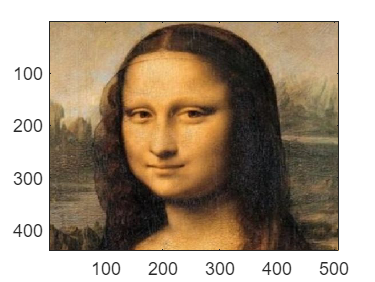

image_1 = read_image('./data/mona.png');

A_1_stretch = [k 0 ; 0 1];
A_1_rotate = [cos(pi/4) -sin(pi/4) ; sin(pi/4) cos(pi/4)];
A_1_total = A_1_rotate * A_1_stretch * A_1_rotate';
t_1 = [0 ; 0];
warped_img_1 = affine_warp(size(image_1).*2, image_1, A_1_total, t_1);
disp('Diagonal Warped Image:')

Diagonal Warped Image:


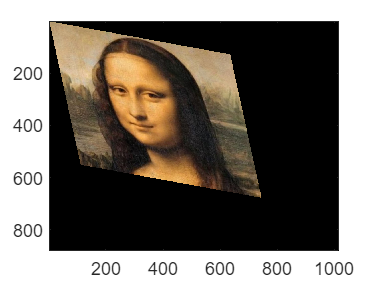

figure, axis image, imagesc(warped_img_1);

## Ex 3.2 Minimum correspondences

What is the minimal number of point correspondences, K, required in order to estimate an affine transformation between two images?

**Your answer here with explanation as a comment here.	**	

% Degree of freedom in affine transformation is 6: a, b, c, d, tx, ty. 
% And the minimum number of correspondences would be 3 in order to estimate an
% affine transformation.

% To estimate an affine transformation between two images, it is necessary to have
% at least three point correspondences that are not on the same line. An affine transformation
% has six degrees of freedom, which are three for translation, two for scaling, and
% one for rotation. With three non-collinear point correspondences, there are three equations
% that can be used to solve for the six unknowns, resulting in a unique solution.
% However, if there are more than three correspondences available, a least-squares method
% can be used to estimate the transformation. Inaccurate results may occur if some of
% the correspondences are outliers or if they lie on the same line.


In general, an estimation problem where the minimal of amount of data is used to estimate the unknown parameters is called **a minimal problem**.

Once you have found a proper coordinate transformation between two images, you can use the provided function affine_warp to warp the source image and create a warped image. Let’s try it. 

## Ex 3.3 Trying warping

Load the image mona.png to the variable img. Try running the following code snippet :

img_3 = imread('data/mona.png'); 
A_3_1 = [0.88 -0.48; 0.48 0.88];
A_3_2 = [-0.48 0.88; 0.88 0.48];
t_3 = [100;-100];
target_size = size(img_3);
disp('Warped Image 1:')

Warped Image 1:


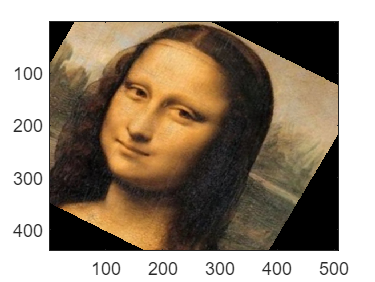

warped_3_1 = affine_warp(target_size, img_3, A_3_1, t_3); imagesc(warped_3_1);

disp('Warped Image 2:')

Warped Image 2:


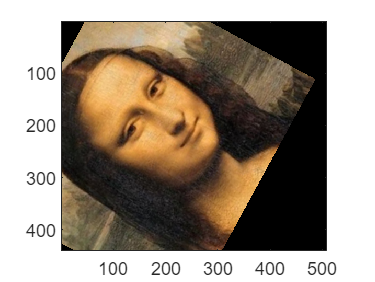

warped_3_2 = affine_warp(target_size, img_3, A_3_2, t_3); imagesc(warped_3_2);
axis image;			

Change the values in A and t to see what happens. First, swap A for eye(2,2) to try a pure translation and plot the result. Then, swap A and t for a stretching along a diagonal as in Ex 3.1 but without rotating and translating the image. Plot the result.

A_3_eye = eye(2,2);
t_3_eye = [50 ; 50];
disp('Warped Image')

Warped Image


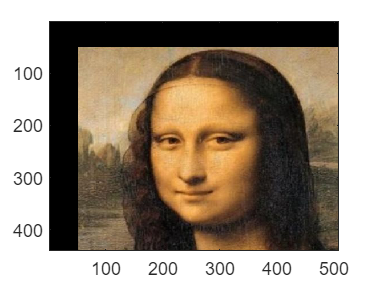

warped_3_eye = affine_warp(size(img_3), img_3, A_3_eye, t_3_eye);
figure, axis image, imagesc(warped_3_eye);


A_3_stretch = [k 0 ; 0 1];
A_3_rotate = [cos(pi/4) -sin(pi/4) ; sin(pi/4) cos(pi/4)];
A_3_total = A_3_rotate * A_3_stretch * A_3_rotate';
t_3 = [10 ; 20];
disp('Warped Image')

Warped Image


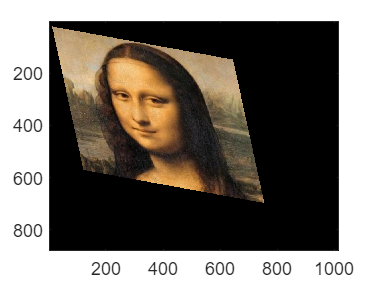

warped_3_3 = affine_warp(size(img_3)*2, img_3, A_3_total, t_3);
figure, axis image, imagesc(warped_3_3);

Explain what you observe in the two cases. **Write your answer as a comment here.**

% In the first case, the image is just moved to a specified direction with
% respect to the values of t. It means that x and y changed to x+t and y+t.

%In the second case, the image is stretched in diagonal direction and as
%can be seen, the image exceeds the boarders of the image.

## Ex 3.4 Writing test case				

For any estimation task it is a good idea to have at least one test case where you know what the answer should be. In this exercise you should make such a test case for RANSAC. Start by generating random points, `pts`, and a random transformation. Then transform these points to create a `pts_tilde`. If you want to make it more realistic, add random noise to the points. You now have two sets of points related by a known affine transformation as in *Ex 3.2*. In the following exercises you will try to estimate this transformation. As you know the correct answer it is easy to detect if you make a mistake. 					

**Make a function** 

that generates a test case for estimating an affine transformation. The transformation should map `pts` to `pts_tilde.` Don't add any outliers now. Outputs `pts` and `pts_tilde` should be `2 x N-arrays`. Also output the *true* transformation, so you know what to expect from your code.

After you have written the function, test it with a few runs here :

N_4 = 100;
[pts_4, pts_tilde_4, A_true_4, t_true_4] = affine_test_case(N_4)

pts_4 =     0.8147    0.1270    0.6324    0.2785    0.9575    0.1576    0.9572    0.8003    0.4218    0.7922    0.6557    0.8491    0.6787    0.7431    0.6555    0.7060    0.2769    0.0971    0.6948    0.9502    0.4387    0.7655    0.1869    0.4456    0.7094    0.2760    0.6551    0.1190    0.9597    0.5853    0.7513    0.5060    0.8909    0.5472    0.1493    0.8407    0.8143    0.9293    0.1966    0.6160    0.3517    0.5853    0.9172    0.7572    0.3804    0.0759    0.5308    0.9340    0.5688    0.0119
    0.9058    0.9134    0.0975    0.5469    0.9649    0.9706    0.4854    0.1419    0.9157    0.9595    0.0357    0.9340    0.7577    0.3922    0.1712    0.0318    0.0462    0.8235    0.3171    0.0344    0.3816    0.7952    0.4898    0.6463    0.7547    0.6797    0.1626    0.4984    0.3404    0.2238    0.2551    0.6991    0.9593    0.1386    0.2575    0.2543    0.2435    0.3500    0.2511    0.4733    0.8308    0.5497    0.2858    0.7537    0.5678    0.0540    0.7792    0.1299    0.4694 

pts_tilde_4 =     1.6108    1.1738    0.8373    0.9740    1.7508    1.2400    1.3614    0.9815    1.3657    1.6399    0.8022    1.6558    1.4030    1.1479    0.9120    0.8315    0.5666    1.0816    1.0558    0.9909    0.9431    1.4893    0.8686    1.1624    1.4203    1.0802    0.9048    0.8319    1.2454    0.9095    1.0418    1.2441    1.7033    0.8158    0.6559    1.0988    1.0730    1.2335    0.6812    1.1318    1.2516    1.1740    1.1737    1.4503    1.0567    0.4434    1.3251    1.0580    1.0982    0.6320
    1.7301    1.4737    1.2304    1.3358    1.8156    1.5158    1.5600    1.3176    1.5866    1.7502    1.2063    1.7581    1.5997    1.4293    1.2784    1.2233    1.0684    1.4145    1.3710    1.3171    1.3084    1.6525    1.2707    1.4521    1.6097    1.4057    1.2737    1.2496    1.4837    1.2798    1.3594    1.5030    1.7874    1.2200    1.1327    1.3928    1.3771    1.4773    1.1472    1.4244    1.5148    1.4535    1.4386    1.6273    1.3856    0.9965    1.5551    1.3618    1

A_true_4 =     0.6443    0.8116
    0.3786    0.5328


t_true_4 =     0.3507
    0.9390


## Ex 3.5 Writing a minimal solver

Make a minimal solver for the case of affine transformation estimation. In other words, **make a function**

that estimates an affine transformation mapping `pts` to `pts_tilde`, where `pts` and `pts_tilde` are `2 x K - arrays` and `K` is the number you found in *Ex 3.2*. Try your function on points from the test case in *Ex 3.4*.

[A_5, t_5] = estimate_affine ( pts_4 , pts_tilde_4)

A_5 =     0.6443    0.8116
    0.3786    0.5328


t_5 =     0.3507
    0.9390


disp(['Average error of A: ' num2str(mean(abs(A_5 - A_true_4), 'all'))])

Average error of A: 2.6368e-16


disp(['Average error of t: ' num2str(mean(abs(t_5 - t_true_4), 'all'))])

Average error of t: 1.9429e-16


## Ex 3.6 Computing residuals

Make a function

that computes the lengths of 2D residual vectors. The function should return an array with N values. *Hint : *Given a `2 x N` matrix, stored in `M`, the column-wise sum of the **squared** elements can be computed as `sum(M.^2, 1)`.

**Verify** that for no outliers and no noise, you get zero residual lengths given the true transformation:

res_6_1 = residual_lgths(A_true_4, t_true_4, pts_4, pts_tilde_4);
disp('nonzero residuals for true transformation:')

nonzero residuals for true transformation:


disp(res_6_1) 

     0



res_6_2 = residual_lgths(A_5, t_5, pts_4, pts_tilde_4);
disp('nonzero residuals for for estimated transformtaion:')

nonzero residuals for for estimated transformtaion:


disp(res_6_2)

   100



## **Ex 3.7 Test case with outliers**

Modify your function `affine_test_case `to create a new function `affine_test_case_outlier `that takes a parameter `outlier_rate` and produces a fraction of outliers among the output points. For example, if `outlier_rate` is 0.2, then 80% of the samples will be related by `pts_tilde = A_true * pts + t_true`. While for the remaining 20%, pts_tilde can be distributed uniformly within some range. 

**Test your code here:**

outlier_rate_7_1 = 0.2;
N_7 = 100;
[pts_7_1, pts_tilde_7_1, A_7_1, t_7_1] = affine_test_case_outlier(N_7, outlier_rate_7_1);
disp(['residuals for outlier rate = ' num2str(outlier_rate_7_1) ' is: '])

residuals for outlier rate = 0.2 is: 


disp(residual_lgths(A_7_1, t_7_1, pts_7_1, pts_tilde_7_1))

    20



outlier_rate_7_2 = 0;
[pts_7_2, pts_tilde_7_2, A_7_2, t_7_2] = affine_test_case_outlier(N_7, outlier_rate_7_2);
disp('residuals without outlier is: ')

residuals without outlier is: 


disp(residual_lgths(A_7_2, t_7_2, pts_7_2, pts_tilde_7_2))

     0



## **Ex 3.8 Writing a RANSAC based solver**

Make a function					

that uses RANSAC to find an affine transformation between two sets of points. (Like before the transformation should map `pts` to `pts_tilde`.) Test your function on test cases generated with your function `affine_test_case_outlier`. 

**RANSAC Note** : You can use the notes to decide on the number of RANSAC iterations needed given your required confidence and estimated inlier ratio. You can also use fixed iterations but make sure that you have enough iterations to find a reasonable solution.

**Verify your code here**. Try different outlier rates. Make sure that you get the right transformation for a reasonable outlier rate as well. 

threshold_8 = 10;
outlier_rate_8 = 0.8;
N_8 = 100;
[pts_8, pts_tilde_8, A_true_8, t_true_8] = affine_test_case_outlier(N_8, outlier_rate_8);

A_true_8

A_true_8 =     0.2801    0.8949
    0.3498    0.6322


t_true_8

t_true_8 =     0.5051
    0.5295



[A_ransac_8, t_ransac_8] = ransac_fit_affine(pts_8, pts_tilde_8, threshold_8);

Number of inliers: 100
Mean residual: 0.7106



A_ransac_8

A_ransac_8 =     0.2801    0.8949
    0.3498    0.6322



t_ransac_8

t_ransac_8 =     0.5051
    0.5295



disp('Average error of A: ' )

Average error of A: 


disp(mean(abs(A_ransac_8 - A_true_8), 'all'))

   1.2490e-16




disp('Average error of t: ')

Average error of t: 


disp(mean(abs(t_ransac_8 - t_true_8), 'all'))

   5.5511e-17



## Ex 3.9 Aligning images

For this exercise, you should use the function

in a similar way as in *Lab 1* to extract SIFT features. Note that it only works for grayscale images, so if you have a colour image you need to convert it to grayscale before with `rgb2gray`. To match features you can use the built-in function matchFeatures. To use the Lowe criterion (with threshold 0.8) you should use the following options: 

that uses SIFT and RANSAC to align the `source` image to the `target` image with `thresh` as the residual threshold for counting inliers in your RANSAC. To perform the actual warping, use the `affine_warp` function within your `align_images` function. Be very careful about the order in which you send the points to RANSAC. You can visualize your correspondences with **showMatchedFeatures**.

**Align **`vermeer_source.png` to `vermeer_target.png using` your `align_images` function. Plot the source, target and warped source images together.

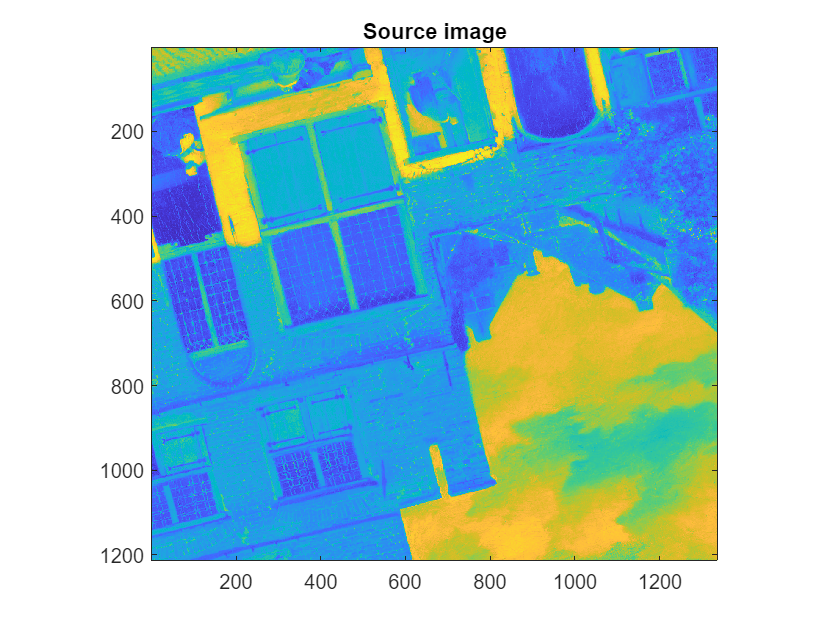


threshold_9 = 20;

img_src = rgb2gray(imread('./data/vermeer_source.png'));
img_tgt = rgb2gray(imread('./data/vermeer_target.png'));

warped_9 = align_images(img_src, img_tgt, threshold_9);

figure, imagesc(img_src);axis image, title('Source image');

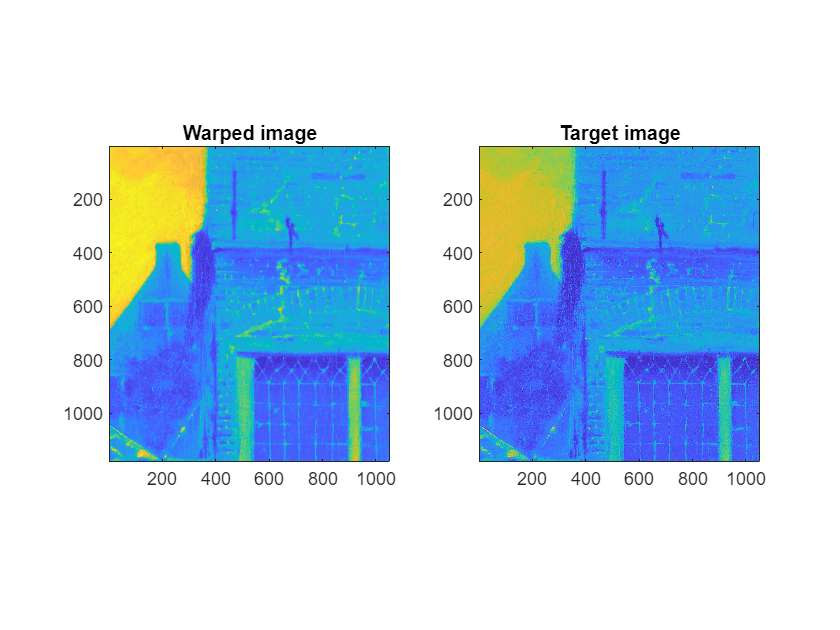


figure;
subplot(1,2,1);
imagesc(warped_9); axis image; title('Warped image');

subplot(1,2,2);
imagesc(img_tgt); axis image; title('Target image');

## Ex 3.10 Aligning images with known orientation

Medical images often have less local structure, making SIFT matching more difficult. It often works better if we drop the rotation invariance. The provided feature extraction function has an option for this. 

assumes that the image has a default orientation. Plot the warped and the target images next to each other to verify your result. Modify your `align_images` function to create function `align_images_v2 `so that it also takes a boolean argument, `upright` stating whether the images have the same orientation, i.e. 

Try aligning the images *CT_1.jpg* and *CT_2.jpg*. Try with and without rotation invariance and try different outlier thresholds. If you are still not successful, try the alternative descriptor SURF which is also implemented in MATLAB with

Also plot the warped image and the target image next to each other so one can verify the result (if successful).

disp('Source Image is:')

Source Image is:


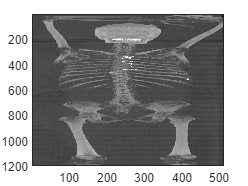

img_src_10 = read_as_grayscale('./data/CT_1.jpg'); 

disp('Target Image is:')

Target Image is:


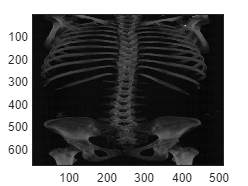

img_tgt_10 = read_as_grayscale('./data/CT_2.jpg');


upright_10 = true;
threshold_10 = 20;

disp('Warped Image with SIFT method is:')

Warped Image with SIFT method is:


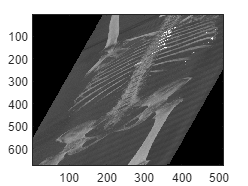

warped_10_SIFT = align_images_v2(img_src_10, img_tgt_10, threshold_10, upright_10);
       
imagesc(warped_10_SIFT)


disp('Warped Image with SURF method is:')

Warped Image with SURF method is:


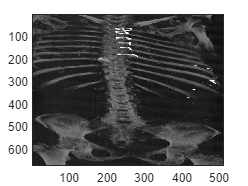

warped_10_SURF = align_images_v2(img_src_10, img_tgt_10, threshold_10, upright_10, "SURF");
imagesc(warped_10_SURF)

**Explain your observations of using and not using rotation invariance at different thresholds here.**

% Here by using the rotation invariance, the results get better visually. Another parameter
% that has an effect on the performance of warping, is the maxratio at
% matchfeatures function, by decreasing it, we decrease the number of
% correspondences and it helps the algorithm to detect better. Because in
% this case there are many similar patterns in the image and big number of
% points could confuse the algorithm.
% in addition, the threshold is anothe parameter that influences the output. 

## Ex 3.11 Flouroscent image example (optional)

Try aligning *tissue_fluorescent.tif *and *tissue_brightfield.tif*. In the fluorescent image, the intensities are basically inverted, so you need to invert one of the images before computing descriptors. (Otherwise you won’t get any good matches.) You can invert it by taking 

Plot the warped image and the target image side by side so one can verify the result.

Note that this example is optional due to the fact it may be hard to get good correspondences with MATLAB's implementation of SIFT.

# Warping

## Ex 3.12 Get pixel value

So far you have used Matlab's function for warping. The reason is that it is difficult to write a Matlab function for warping that is not painfully slow. Now you will get to write one anyway, but we will only use it for very small images. 

**Write a function**

that gives you the pixel value at `position`. If the elements of `position` are not integers, select the value at the closest pixel. If it is outside the image, return 1 (=white). Try your function on a simple image to make sure it works. 

Image_12 = rand(4,4)

Image_12 =     0.3299    0.0412    0.6295    0.9216
    0.9927    0.0565    0.9358    0.5928
    0.7607    0.0289    0.6876    0.7608
    0.9470    0.3334    0.1129    0.1693


value_11_1 = sample_image_at(Image_12, [1.9 , 2.2])

value_11_1 = 0.0565

value_11_2 = sample_image_at(Image_12, [1.1 , 3.9]) 

value_11_2 = 0.9216

value_11_3 = sample_image_at(Image_12, [-2 , 0.5]) 

value_11_3 = 1

## Ex 3.13 Warp

Now, you will do a warping function that warps a `16 x 16` image according to the coordinate transfomation provided in `transform_coordinates.m`. 

Write a function 

that warps source according to `transform_coordinates` and forms an output `16 X 16` image warped. Use your function `sample_image_at` to extract pixel values. Try the function on `source_16x16.tif` and plot the answer using imagesc. You will get to see a meaningful image if you get it right.

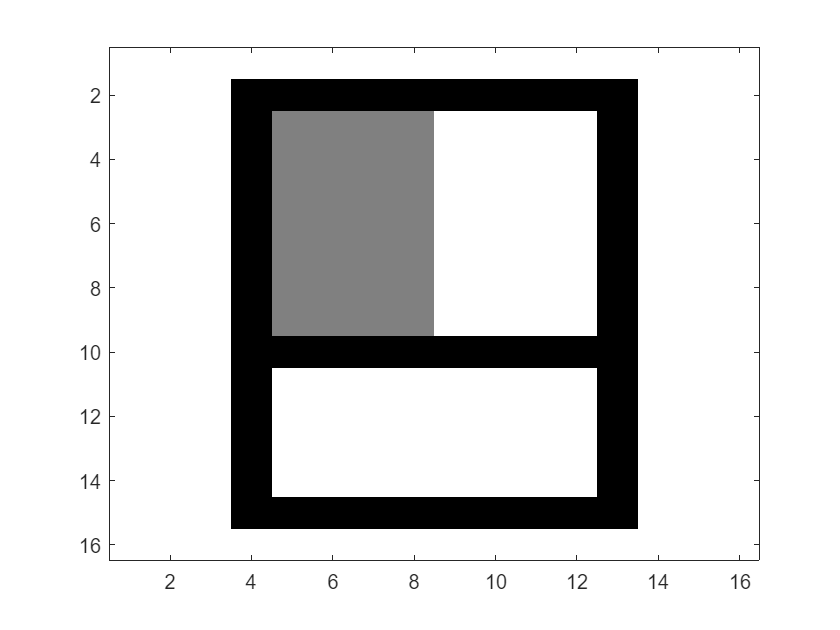

source_13 = read_as_grayscale('./data/source_16x16.tif');

warped_13 = warp_16x16 (source_13);
disp('source Image:')

source Image:


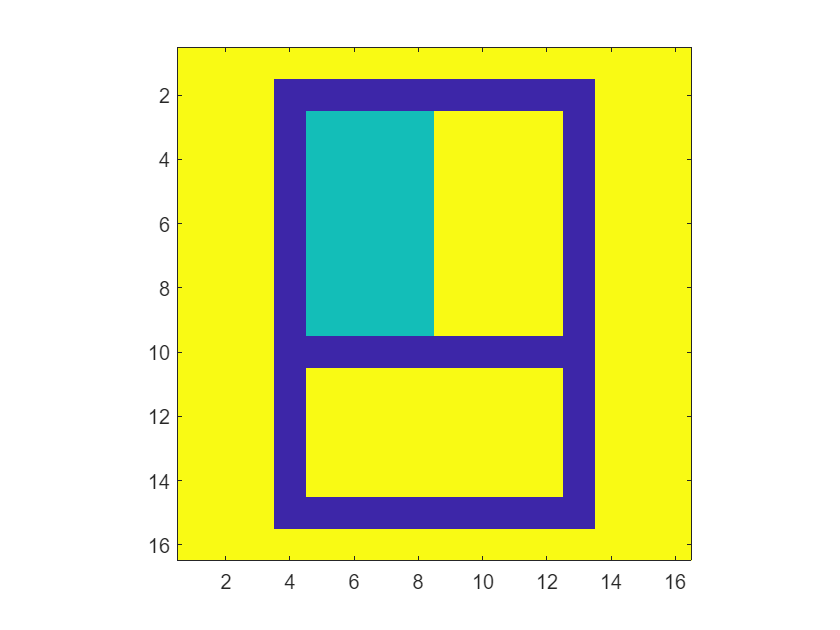

figure, imagesc(source_13); axis image

disp('Warped Image:')

Warped Image:


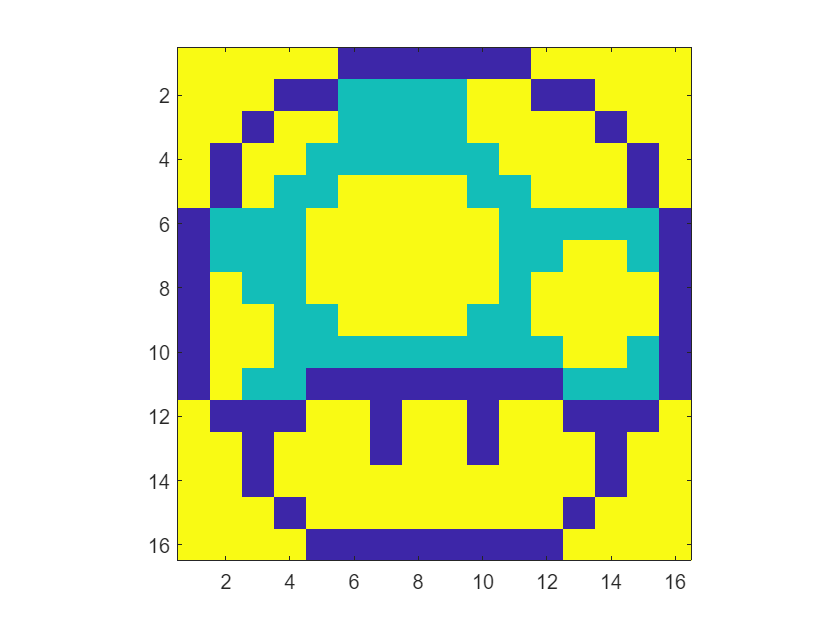

figure, imagesc(warped_13); axis image

# Least Squares

## Ex 3.14 LS

Write a function

that estimates an affine transformation mapping `pts` to `pts_tilde `in least squares sense, i.e., all points in `pts` and `pts_tilde` are used to compute the transformation. (Depending on how you wrote you estimate_affine.m, this might be very easy.) Use it on the inliers from RANSAC to refine the estimate. Add this to `align_images `to form a new function` dalign_images_inlier_ls` and test it on the `Vermeer` images for different outlier thresholds. Plot the final result images next to each other.

Threshold is: 30


num_inliers = 4

num_inliers_final = 365

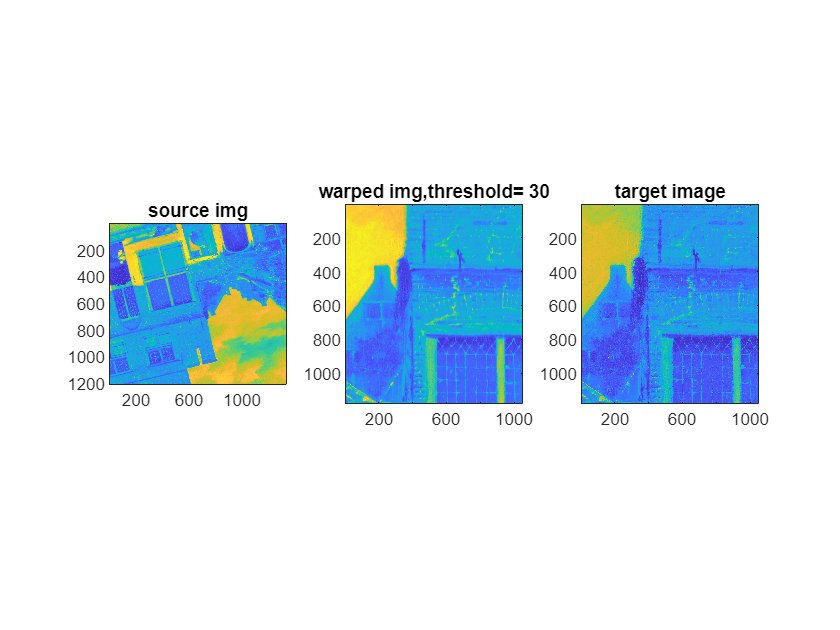

Threshold is: 50


num_inliers = 12

num_inliers_final = 368

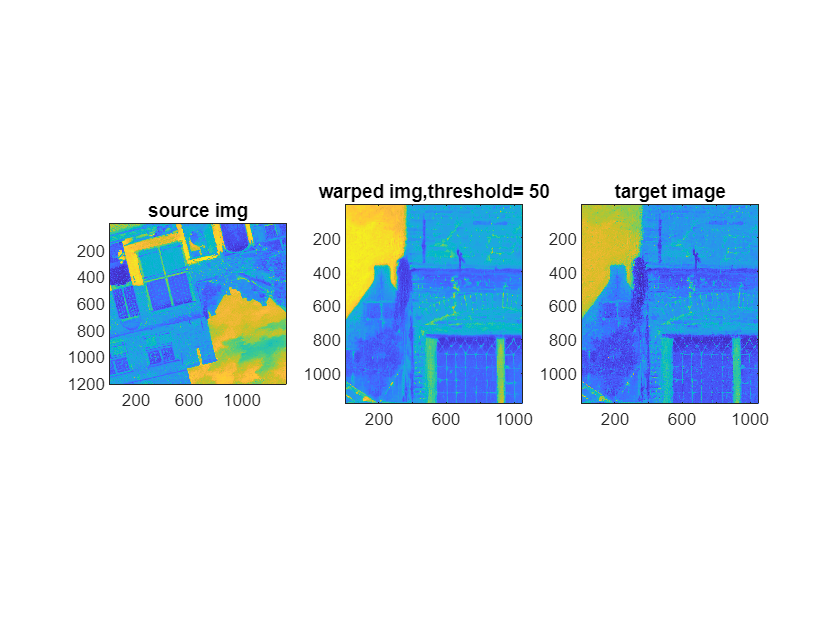

Threshold is: 80


num_inliers = 3

num_inliers_final = 370

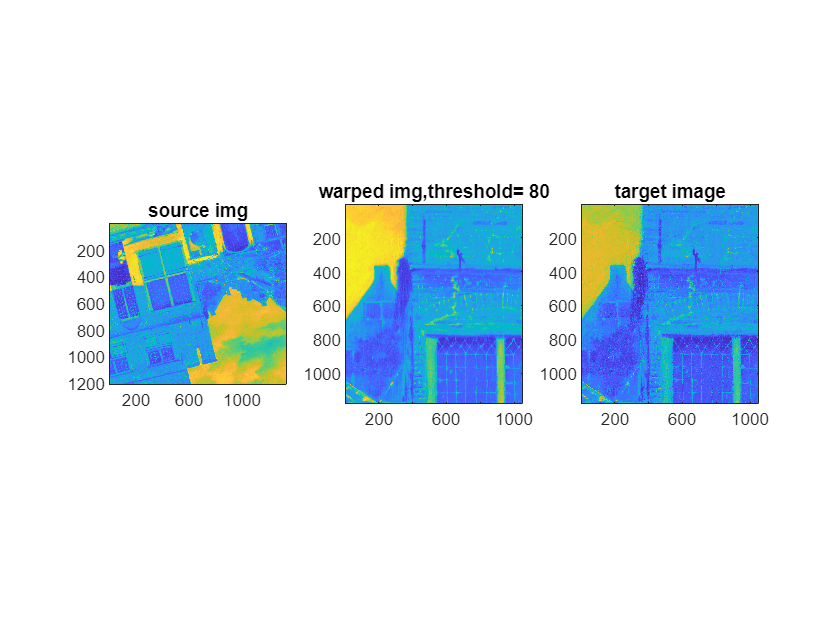

Threshold is: 100


num_inliers = 3

num_inliers_final = 370

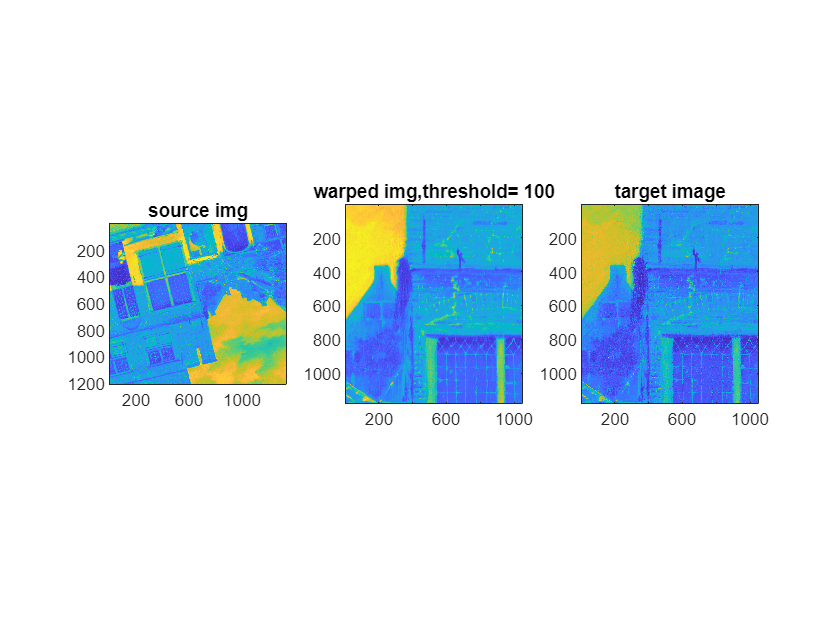

img_src_14 = rgb2gray(imread('./data/vermeer_source.png'));
img_tgt_14 = rgb2gray(imread('./data/vermeer_target.png'));

for thresh_14 = [30,50,80,100]
    
    disp(['Threshold is: ' num2str(thresh_14)])
    warped_14 = align_images_inlier_ls(img_src_14, img_tgt_14, thresh_14, false);
    
    figure;
    subplot(1,3,1);
    imagesc(img_src_14); axis image; title('source img');
    subplot(1,3,2);
    imagesc(warped_14); axis image; title(['warped img,threshold= ' num2str(thresh_14)]);
    subplot(1,3,3);
    imagesc(img_tgt_14); axis image; title('target image');
    
end

Do you notice an improvement? Observe visually and also in terms of the residuals. **Explain your observations and the plausible reasons behind them as comment here.**

% There are not any significant difference visually, but as can be seen, the number of inliers
% increased significantly in compare to previous excersizes.

% Since we're using the generated inliers in RANSAC for estimating the
% transformation, the estimated A & t are more accurate that previous
% parts.